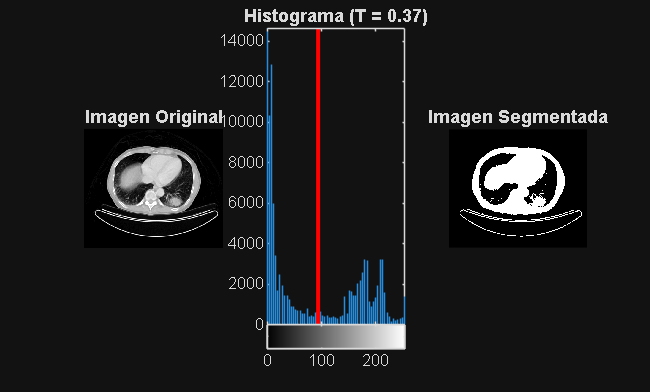

%% Script Principal: Segmentación Woods-Gonzalez

% 1. Cargar la imagen
% Nota: He cambiado la ruta a una imagen de ejemplo de MATLAB para que sea funcional 
% inmediatamente. Cambia 'coins.png' por tu ruta: "C:\Users\Jorge\...\Prueba.png"
I = Prueba;

% Convertir a escala de grises si es necesario
if size(I, 3) == 3
    Igray = rgb2gray(I);
else
    Igray = I;
end

% 2. Llamada a la función de segmentación
% Usamos un criterio de convergencia de 0.01 (ajustable)
Criterio = 0.01;
Tseg = segWoodsGonzalez(Igray, Criterio);

% 3. Aplicar el umbral final para segmentar
Ibinary = im2bw(Igray, Tseg);

% 4. Visualización de resultados
figure(1);
subplot(1,3,1);
imshow(Igray);
title('Imagen Original');

subplot(1,3,2);
imhist(Igray);
hold on;
% Dibujar una línea roja donde quedó el umbral
line([Tseg*255 Tseg*255], get(gca, 'YLim'), 'Color', 'r', 'LineWidth', 2);
title(['Histograma (T = ', num2str(Tseg, 3), ')']);

subplot(1,3,3);
imshow(Ibinary);
title('Imagen Segmentada');


fprintf('El umbral óptimo calculado es: %.4f\n', Tseg);

El umbral óptimo calculado es: 0.3702



%% --- FUNCIÓN DE SEGMENTACIÓN (Algoritmo de Woods & Gonzalez) ---
function T_new = segWoodsGonzalez(I, Criterio)
    % Convertimos a double para que los valores estén en el rango [0, 1]
    I = im2double(I);
    
    % Paso 1: Estimado inicial (promedio de intensidad de la imagen)
    T_new = mean(I(:)); 
    T_old = 0;
    
    % Iniciamos el proceso iterativo
    while abs(T_new - T_old) > Criterio
        T_old = T_new;
        
        % Paso 2: Crear grupos G1 y G2 (Indexación lógica)
        G1 = I < T_old;
        G2 = I >= T_old;
        
        % Paso 3: Obtener medias de intensidad m1 y m2
        % Validamos que los grupos no estén vacíos para evitar errores NaN
        if any(G1(:))
            m1 = mean(I(G1));
        else
            m1 = 0;
        end
        
        if any(G2(:))
            m2 = mean(I(G2));
        else
            m2 = 0; 
        end
        
        % Paso 4: Calcular el nuevo umbral (Promedio de las medias)
        T_new = (m1 + m2) / 2;
        
        % El ciclo se repite hasta que la diferencia sea <= Criterio
    end
end